# Homework 8  - Farshad Bolouri - R11630884, Brennae Stinson - R11553417

### Problem 1) 

clear
close all
load test_signal.mat
Fs= 500;
N = length(test_signal);
duration = 5;

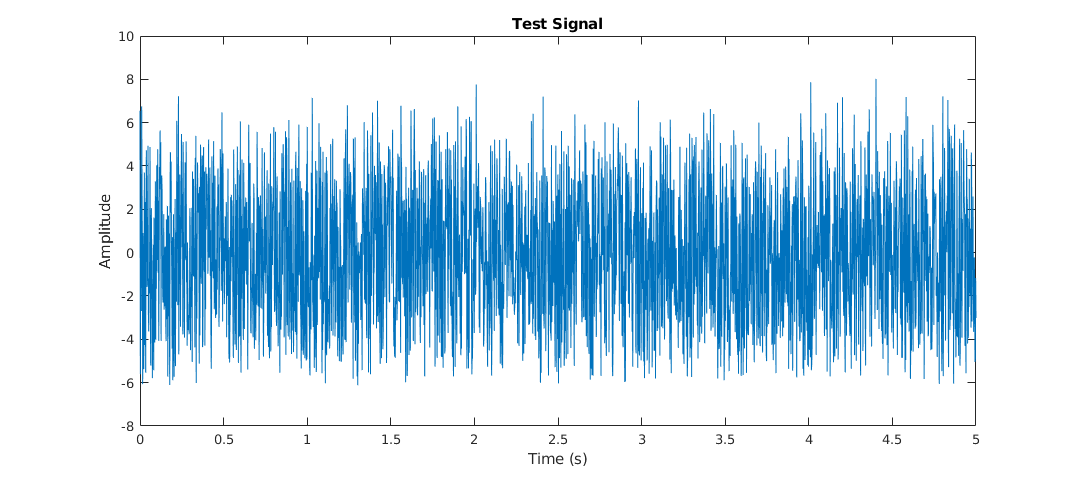

time = linspace(0, duration, N);
graph = figure;
plot(time, test_signal)
title('Test Signal')
xlabel('Time (s)')
ylabel('Amplitude')
set(graph,'Units','normalized','Position',[0 0 1 0.25]);

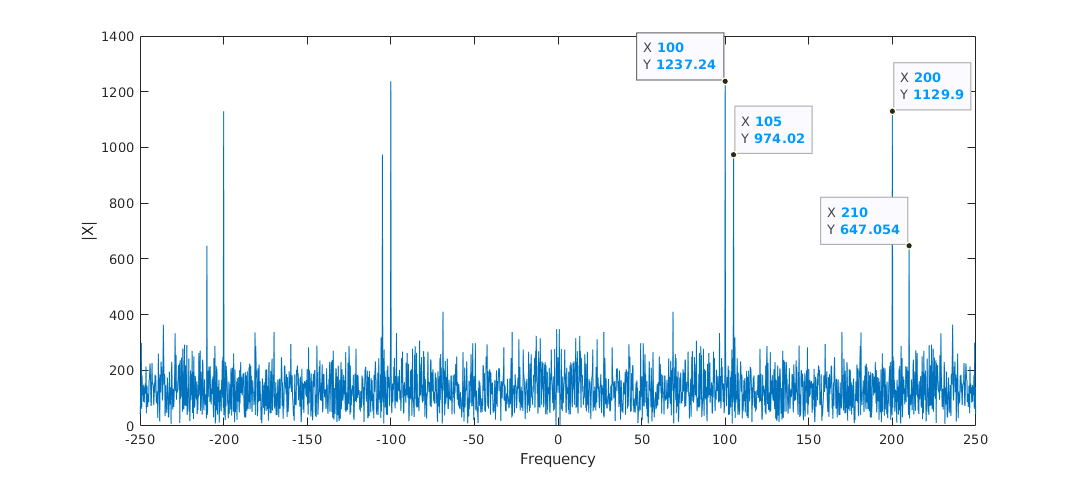

FT = fft(test_signal,2500);

spectrum = abs(fftshift(FT));                  % Zero-Centered FFT
spectrumF = (-N/2:N/2-1)...
    /N*Fs;                   % Zero-Centered Frequency Range

graph = figure;
plot(spectrumF, spectrum)
xlabel('Frequency')
ylabel('|X|')
set(graph,'Units','normalized','Position',[0 0 1 0.25]);

ax = gca;
chart = ax.Children(1);
datatip(chart,105,974);
datatip(chart,210,647.1);
datatip(chart,200,1130);
datatip(chart,100,1237, 'Location', 'northwest');

*This signal seems to consist of 4 different sinusoids with added noise. The frequencies of the sinusoids are 100Hz , 105Hz, 200Hz, and 210Hz. There respective amplitudes are 1237.24,974.02,1129.9, and 647.054.*

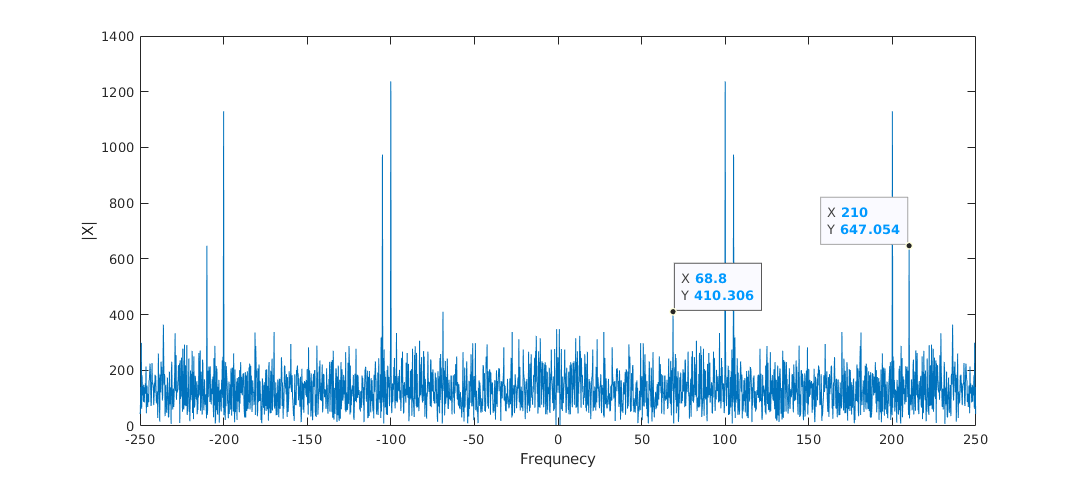

graph = figure;
plot(spectrumF, spectrum)
xlabel('Frequnecy')
ylabel('|X|')
set(graph,'Units','normalized','Position',[0 0 1 0.25]);
ax = gca;
chart = ax.Children(1);
datatip(chart,210,647.1);
datatip(chart, 68.8, 410.3);

*To confirm the points shown in the graph to be the lowest of the four signal frequencies, and the highest of the noise components we can do the following:*

maxAmplitudes= maxk(spectrum(N/2:N), 5);
lowestSinusoidA = maxAmplitudes(4)

lowestSinusoidA = 647.0538

highestNoiseA = maxAmplitudes(5)

highestNoiseA = 410.3063

*This shows that we were indeed correct. Now we'll calculate the SNR in dBs:*

SNR = 20*log10(lowestSinusoidA) - 20*log10(highestNoiseA)

SNR = 3.9566

P = nextpow2(N)

P = 12

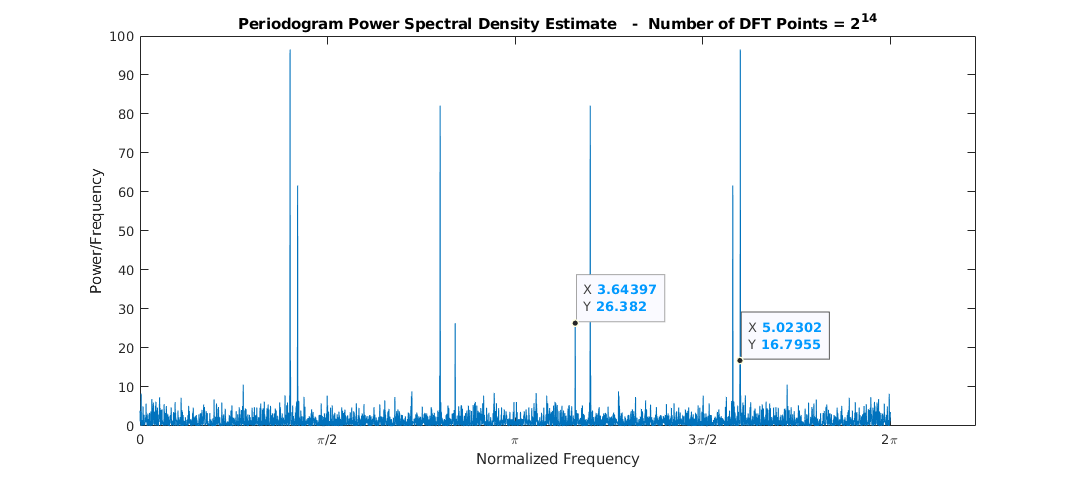

graph = figure;
[pxx14, w14] = periodogram(test_signal, [], 2^(P+2),'twosided','psd');     % Window Type: rectangular window
plot(w14, pxx14)
xlabel('Normalized Frequency')
ylabel('Power/Frequency')
title('Periodogram Power Spectral Density Estimate   -  Number of DFT Points = 2^{14}')
set(graph,'Units','normalized','Position',[0 0 1 0.25]); 
ax = gca;
set(gca,'XTick',0:pi/2:2*pi) 
set(gca,'XTickLabel',{'0','\pi/2','\pi','3\pi/2','2\pi'})
chart = ax.Children(1);
datatip(chart,3.644,26.38);
datatip(chart, 'DataIndex', 13099);

SNR14 = 10*log10(26.38) - 10*log10(16.8)

SNR14 = 1.9597

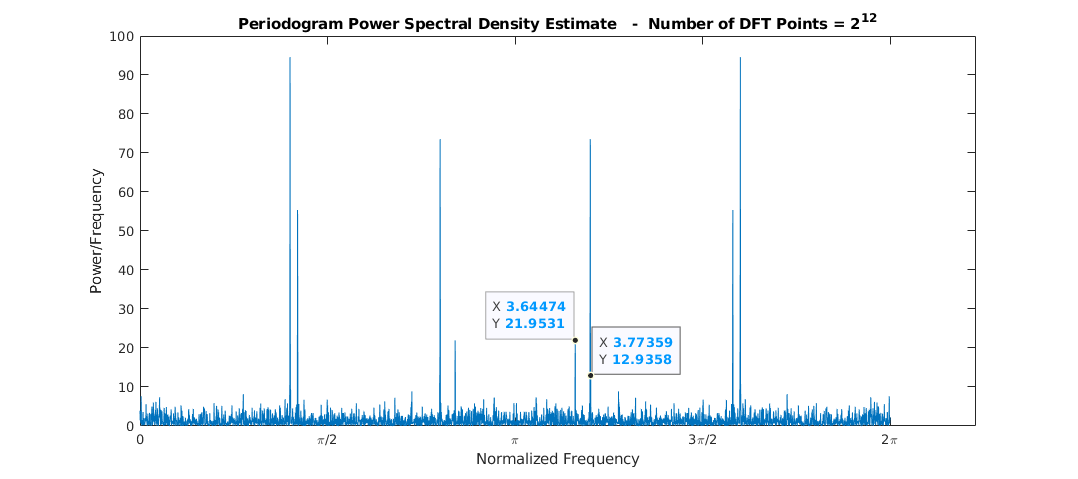

graph = figure;
[pxx12, w12] = periodogram(test_signal, [], 2^P,'twosided','psd');     % Window Type: rectangular window
plot(w12, pxx12)
title('Periodogram Power Spectral Density Estimate   -  Number of DFT Points = 2^{12}')
xlabel('Normalized Frequency')
ylabel('Power/Frequency')
set(graph,'Units','normalized','Position',[0 0 1 0.25]); 
ax = gca;
chart = ax.Children(1);
set(gca,'XTick',0:pi/2:2*pi) 
set(gca,'XTickLabel',{'0','\pi/2','\pi','3\pi/2','2\pi'})
datatip(chart,3.645, 21.95, 'Location', 'northwest');
datatip(chart, 'DataIndex' , 2461);

SNR12 = 10*log10(21.95) - 10*log10(12.94)

SNR12 = 2.2950

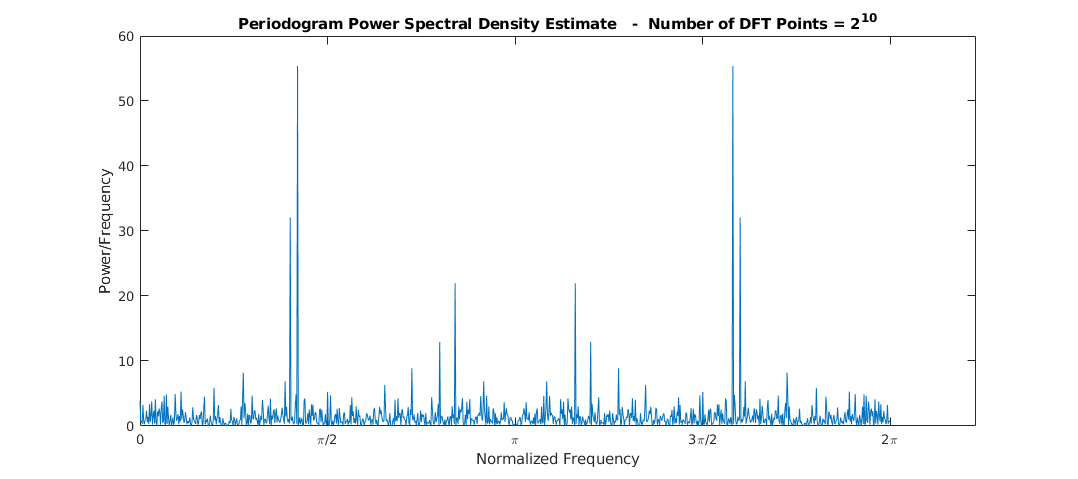

graph = figure;
[pxx10, w10] = periodogram(test_signal, [], 2^(P-2),'twosided','psd');     % Window Type: rectangular window
plot(w10, pxx10)
title('Periodogram Power Spectral Density Estimate   -  Number of DFT Points = 2^{10}')
xlabel('Normalized Frequency')
ylabel('Power/Frequency')
set(graph,'Units','normalized','Position',[0 0 1 0.25]); 
set(gca,'XTick',0:pi/2:2*pi) 
set(gca,'XTickLabel',{'0','\pi/2','\pi','3\pi/2','2\pi'})

*If you compare this plot to the last 2 plots you can see that we are actually missing one of our 4 frequencies. Let's compare them once more:*

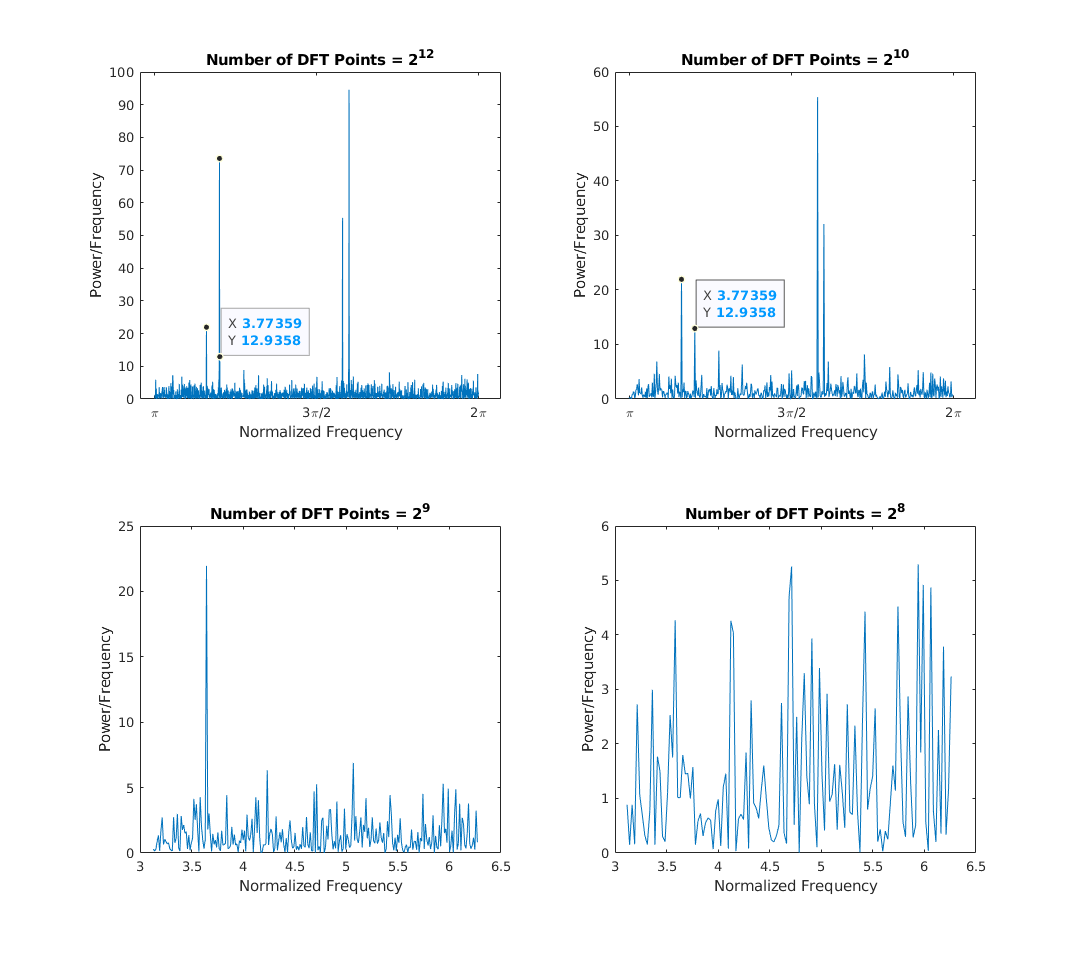

graph = figure;
subplot(2,2,1)
plot(w12(length(pxx12)/2:end), pxx12(length(pxx12)/2:end))
title('Number of DFT Points = 2^{12}')
xlabel('Normalized Frequency')
ylabel('Power/Frequency')

ax = gca;
chart = ax.Children(1);
set(gca,'XTick',pi:pi/2:2*pi) 
set(gca,'XTickLabel',{'\pi','3\pi/2','2\pi'})
datatip(chart,3.771, 73.55, 'Location', 'northwest');
datatip(chart,3.645, 21.95, 'Location', 'northwest');
datatip(chart, 'DataIndex' , 414);

subplot(2,2,2)
plot(w10(length(pxx10)/2:end), pxx10(length(pxx10)/2:end))
title('Number of DFT Points = 2^{10}')
xlabel('Normalized Frequency')
ylabel('Power/Frequency')
set(graph,'Units','normalized','Position',[0 0 1 0.5]); 

ax = gca;
chart = ax.Children(1);
set(gca,'XTick',pi:pi/2:2*pi) 
set(gca,'XTickLabel',{'\pi','3\pi/2','2\pi'})
datatip(chart,3.645, 21.95, 'Location', 'northwest');
datatip(chart, 'DataIndex' , 105);

[pxx9, w9] = periodogram(test_signal, [], 2^(9),'twosided','psd');     % Window Type: rectangular window
subplot(2,2,3)
plot(w9(length(pxx9)/2:end), pxx9(length(pxx9)/2:end))
title('Number of DFT Points = 2^{9}')
xlabel('Normalized Frequency')
ylabel('Power/Frequency')

[pxx8, w8] = periodogram(test_signal, [], 2^(8),'twosided','psd');     % Window Type: rectangular window
subplot(2,2,4)
plot(w8(length(pxx8)/2:end), pxx8(length(pxx8)/2:end))
title('Number of DFT Points = 2^{8}')
xlabel('Normalized Frequency')
ylabel('Power/Frequency')

*Testing on lower orders including N = *$2^9 \;\textrm{and}\;2^8$*indicates as expected a decrease in frequency resolution as the value of N decreases.*

*As a result of this testing we know we cannot use P = 10 for this task. Let's try P = 11:*

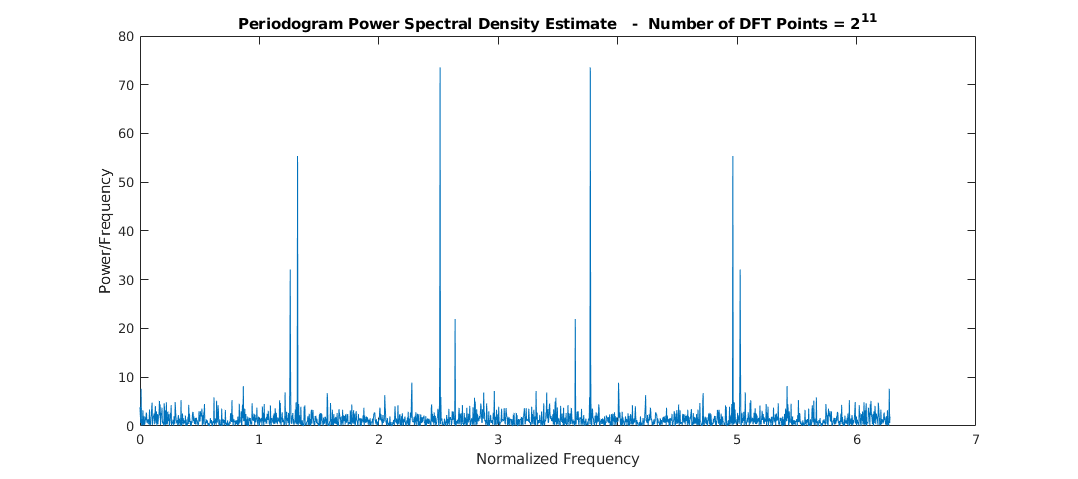

graph = figure;
[pxx11, w11] = periodogram(test_signal, [] , 2^(P - 1),'twosided','psd');     % Window Type: rectangular window
plot(w11, pxx11)
title('Periodogram Power Spectral Density Estimate   -  Number of DFT Points = 2^{11}')
xlabel('Normalized Frequency')
ylabel('Power/Frequency')
set(graph,'Units','normalized','Position',[0 0 1 0.25]); 

*With P = 11 we seem to be still able to see the four frequencies!*

SNR11 = 10*log10(21.95) - 10*log10(8.884)

SNR11 = 3.9283

* We started with first finding P in a way that satifies the equation *$2^P \ge \textrm{length}\;\textrm{of}\;\textrm{the}\;\textrm{test}\;\textrm{signal}$, *in which P = 12.*

*You can see how the behavior of the periodogram changes as we reduce P. As we use the less number of DFT points we are also plotting smaller number of points (calculating FFTs with less points); which results to getting less details in our periodogram (which can result to losing the differentiating factor between the sinusoid frequencies and the noise frequencies). Note that as P is reducing the amplitude of our 4 frequencies are decreasing and eventually disappearing.*

*After trying out the different different nfft's (all powers of 2) as shown above, We found *$2^{11}$* to be the smallest numbers of DFT points we could use while still being able to identify the 4 sinusoid frequencies.  *$2^{11}$ *also produces the highest SNR as shown above.*

*We also tried different window types and found the rectangular window to be the best for this signal.*

## **Problem 2) **

Again, utilize the test signal in the file “test_signal.mat” and estimate the power spectral density, but this time using Welch’s method. 

a) Estimate the power spectral density using Welch’s method, with a rectangular window of N samples. Modify N and observe the behavior.

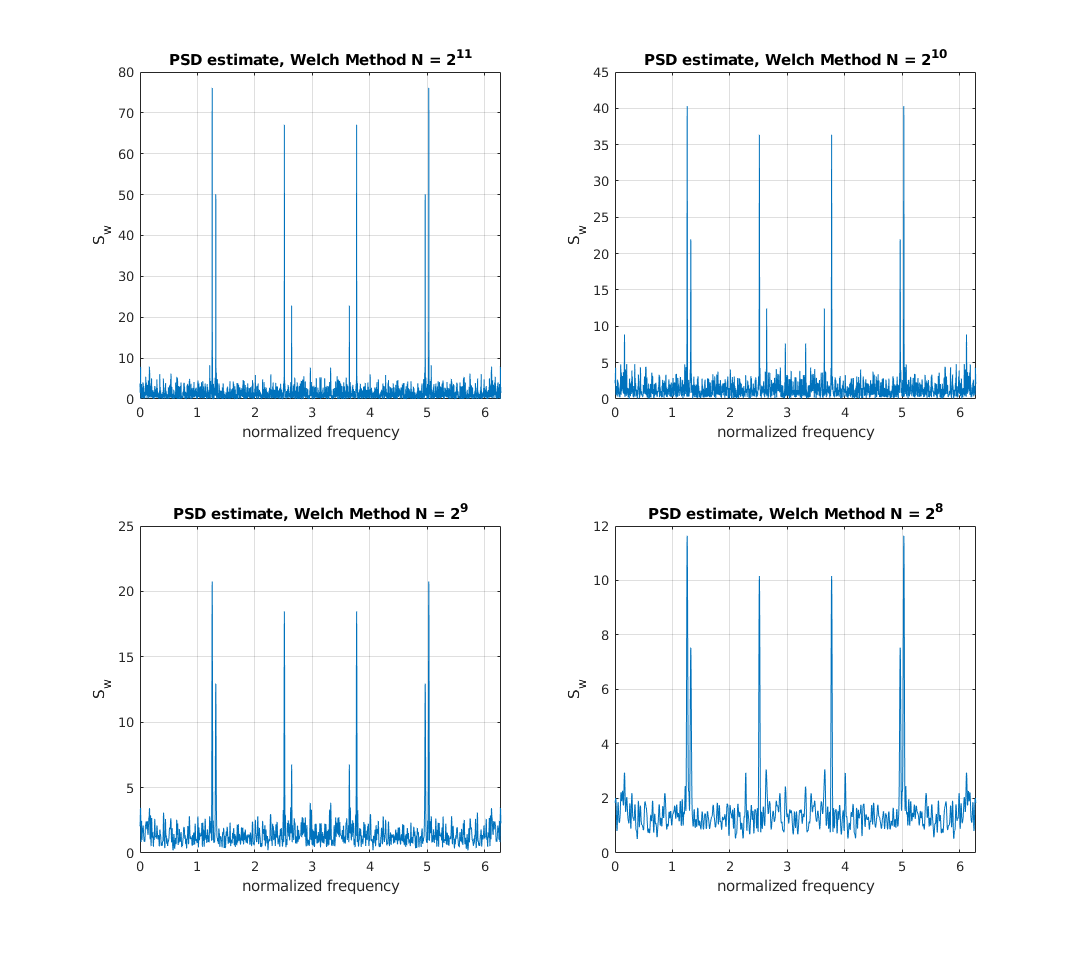

load test_signal.mat
overlap = 70;

[Sw_rectwin_2048,w_1]=pwelch(test_signal,rectwin(2^11),overlap,2500,'twosided','psd');
[Sw_rectwin_1024,w_2]=pwelch(test_signal,rectwin(2^10),overlap,2500,'twosided','psd');
[Sw_rectwin_512,w_3]=pwelch(test_signal,rectwin(2^9),overlap,2500,'twosided','psd');
[Sw_rectwin_256,w_4]=pwelch(test_signal,rectwin(2^8),overlap,2500,'twosided','psd');



graph = figure;
subplot(2,2,1)
set(graph,'Units','normalized','Position',[0 0 1 0.5]); 
plot(w_1,Sw_rectwin_2048)
xlim([0,2*pi])
grid
xlabel('normalized frequency')
ylabel('S_w')
title('PSD estimate, Welch Method N = 2^{11}')

subplot(2,2,2)
plot(w_2,Sw_rectwin_1024)
xlim([0,2*pi])
grid
xlabel('normalized frequency')
ylabel('S_w')
title('PSD estimate, Welch Method N = 2^{10}')


subplot(2,2,3)
plot(w_3,Sw_rectwin_512)
xlim([0,2*pi])
grid
xlabel('normalized frequency')
ylabel('S_w')
title('PSD estimate, Welch Method N = 2^{9}')

subplot(2,2,4)
plot(w_4,Sw_rectwin_256)
xlim([0,2*pi])
grid
xlabel('normalized frequency')
ylabel('S_w')
title('PSD estimate, Welch Method N = 2^{8}')

b) What is the minimum window size N with which you can differentiate the four distinct signal frequencies?

*As you can see, the last N-value which provides all four frequencies is *$N=2^9$*. The PSD estimate at *$N=2^8$* loses frequency resolution to the point where the final frequency spike is difficult to distinguish from noise*.

c) What is the window size N that provides the highest SNR?

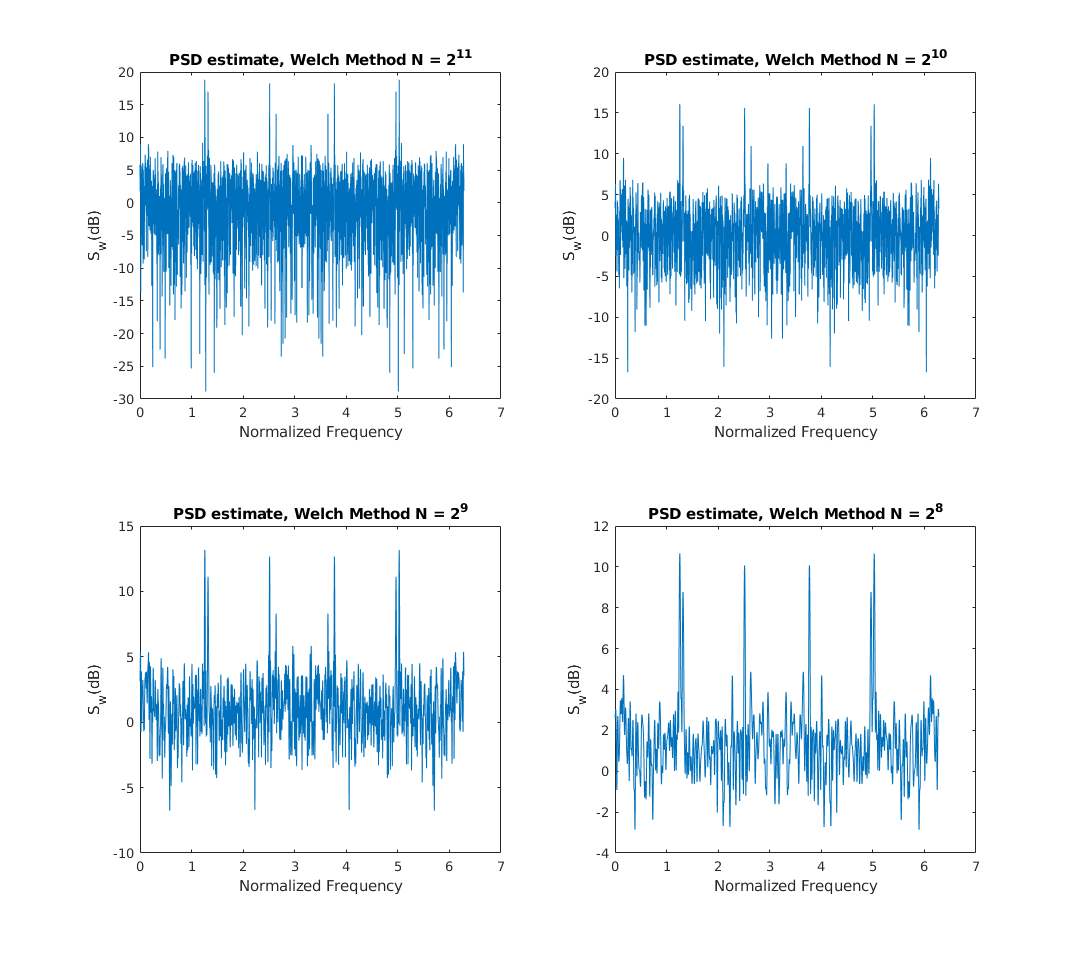

 %plot resulting welch ffts in dB
    graph = figure;
    set(graph,'Units','normalized','Position',[0 0 1 0.5]); 
    subplot(2,2,1);
    plot(w_1,10*log10(Sw_rectwin_2048))
    xlabel('Normalized Frequency')
    ylabel('S_w(dB)')
    title('PSD estimate, Welch Method N = 2^{11}')

    subplot(2,2,2);
    plot(w_2,10*log10(Sw_rectwin_1024))
    xlabel('Normalized Frequency')
    ylabel('S_w(dB)')
    title('PSD estimate, Welch Method N = 2^{10}')

    subplot(2,2,3);
    plot(w_3,10*log10(Sw_rectwin_512))
    xlabel('Normalized Frequency')
    ylabel('S_w(dB)')
    title('PSD estimate, Welch Method N = 2^{9}')

    subplot(2,2,4);
    plot(w_4,10*log10(Sw_rectwin_256))
    xlabel('Normalized Frequency')
    ylabel('S_w(dB)')
    title('PSD estimate, Welch Method N = 2^{8}')

maxAmplitudes= maxk(Sw_rectwin_2048(N/2:N), 5);
lowestSinusoidA = maxAmplitudes(4)

lowestSinusoidA = 22.8483

highestNoiseA = maxAmplitudes(5)

highestNoiseA = 10.2463

SNR = 10*log10(lowestSinusoidA) - 10*log10(highestNoiseA)

SNR = 3.4829

*The highest SNR is again provided by *$N=2^{11}$*. This makes sense as it is the closest N-value to full resolution.*

d) Repeat the exercise using a Hanning window. What is the minimum window size N with which you can differentiate the four distinct signal frequencies? 

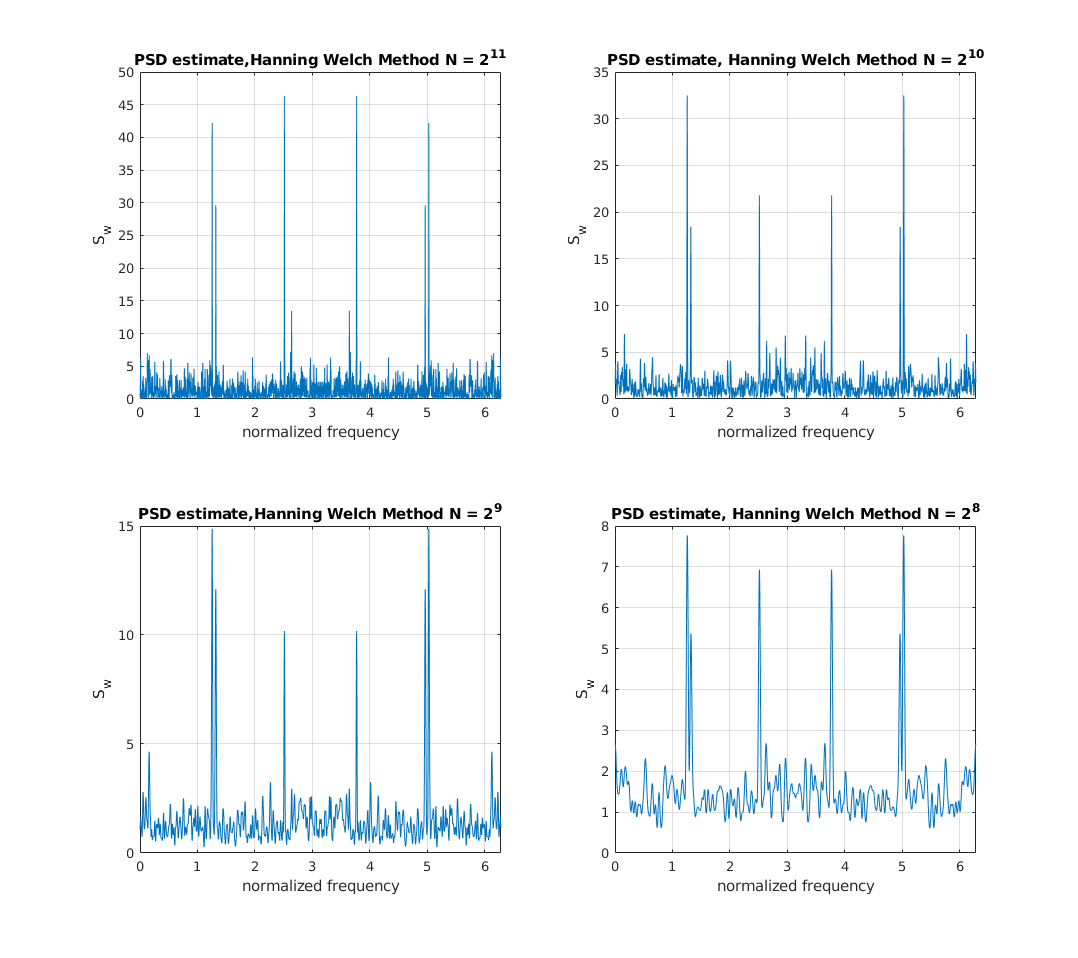

load test_signal.mat
overlap = 70;

[Sw_hann_2048,w_1]=pwelch(test_signal,hann(2^11),overlap,2500,'twosided','psd');
[Sw_hann_1024,w_2]=pwelch(test_signal,hann(2^10),overlap,2500,'twosided','psd');
[Sw_hann_512,w_3]=pwelch(test_signal,hann(2^9),overlap,2500,'twosided','psd');
[Sw_hann_256,w_4]=pwelch(test_signal,hann(2^8),overlap,2500,'twosided','psd');



graph = figure;
subplot(2,2,1)
set(graph,'Units','normalized','Position',[0 0 1 0.5]); 
plot(w_1,Sw_hann_2048)
xlim([0,2*pi])
grid
xlabel('normalized frequency')
ylabel('S_w')
title('PSD estimate,Hanning Welch Method N = 2^{11}')

subplot(2,2,2)
plot(w_2,Sw_hann_1024)
xlim([0,2*pi])
grid
xlabel('normalized frequency')
ylabel('S_w')
title('PSD estimate, Hanning Welch Method N = 2^{10}')


subplot(2,2,3)
plot(w_3,Sw_hann_512)
xlim([0,2*pi])
grid
xlabel('normalized frequency')
ylabel('S_w')
title('PSD estimate,Hanning Welch Method N = 2^{9}')

subplot(2,2,4)
plot(w_4,Sw_hann_256)
xlim([0,2*pi])
grid
xlabel('normalized frequency')
ylabel('S_w')
title('PSD estimate, Hanning Welch Method N = 2^{8}')

*The lowest N-value at which the frequencies can be seen is *$N=2^{11}$*. Using this method, the N-value must be very close to full resolution to see all four frequencies.*

What is the window size N that provides the highest SNR?

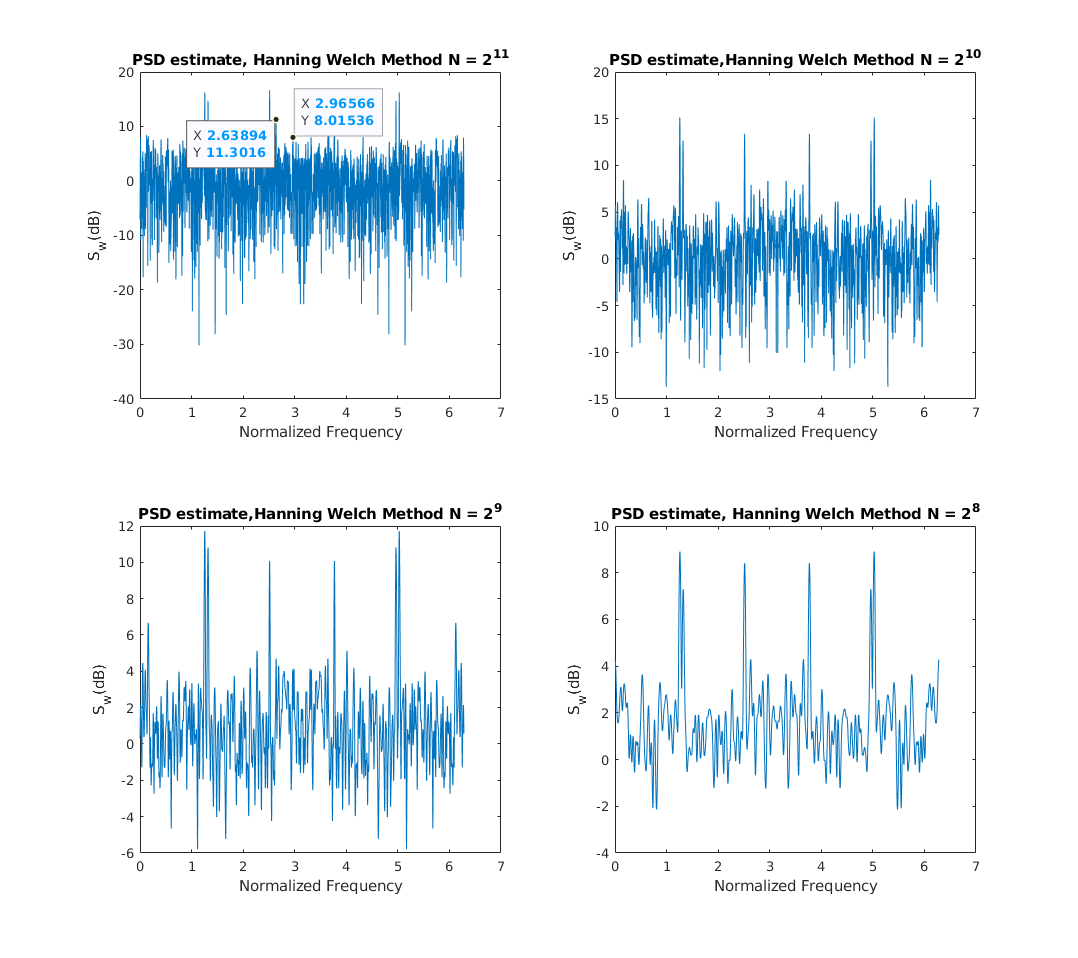

%plot resulting welch ffts in dB
graph = figure;
set(graph,'Units','normalized','Position',[0 0 1 0.5]); 
subplot(2,2,1);
plot(w_1,10*log10(Sw_hann_2048))
xlabel('Normalized Frequency')
ylabel('S_w(dB)')
title('PSD estimate, Hanning Welch Method N = 2^{11}')

subplot(2,2,2);
plot(w_2,10*log10(Sw_hann_1024))
xlabel('Normalized Frequency')
ylabel('S_w(dB)')
title('PSD estimate,Hanning Welch Method N = 2^{10}')

subplot(2,2,3);
plot(w_3,10*log10(Sw_hann_512))
xlabel('Normalized Frequency')
ylabel('S_w(dB)')
title('PSD estimate,Hanning Welch Method N = 2^{9}')

subplot(2,2,4);
plot(w_4,10*log10(Sw_hann_256))
xlabel('Normalized Frequency')
ylabel('S_w(dB)')
title('PSD estimate, Hanning Welch Method N = 2^{8}')

subplot(2,2,1)
ax2 = gca;
chart2 = ax2.Children(1);
datatip(chart2,2.966,8.015);
datatip(chart2,2.639,11.3,'Location','southwest');

SNR = 11.0316 - 8.01536

SNR = 3.0162

*Again, the highest SNR is from the PSD estimate with an N-value of *$N=2^{11}$*.*

e) Comment on the effect of using windowing in this method.

Windowing alters the spectral leakage of the fft of the signal at the expense of frequency resolution. The Hanning window provides a similar result to the rectangular window except with less laekage and lower SNR. This observation proves that the Hanning window is best suited for this method over the Rectangular Window.

 f) Comment on the advantages and disadvantages of Welch’s method compared to Bartlett’s method.

Welch's method improves Bartlett's method by decreasing the signal variance. The Welch's method provides better precision but less frequency resolution than Bartlett's method.

## Problem 3)

 A digital LTI system is implemented in the file “hidden_system.p”. This is an obfuscated Matlab file that behaves like a regular .m function file, but you cannot observe the contents of it. The hidden system takes one argument that is a vector of digital samples, and produces a vector of digital samples after passing through the system:

y=hidden_system(x) % x is the vector containing the input signal and y is vector containing the output signal 

Your task is to estimate the transfer function of the hidden system and describe its behavior. We studied three different methods for system identification:

1. Direct application of an impulse signal, with repeated experiments 

2. Application of a random input signal, using autocorrelation 

3. Feeding a single frequency at a time, and sweeping

a) Select one of the three methods above. Using the method chosen, estimate the transfer function of the system, in the frequency domain (magnitude and phase). Modify the method parameters until the transfer function can be clearly observed.

*Direct application of a delta function was used for this problem in MATLAB.*

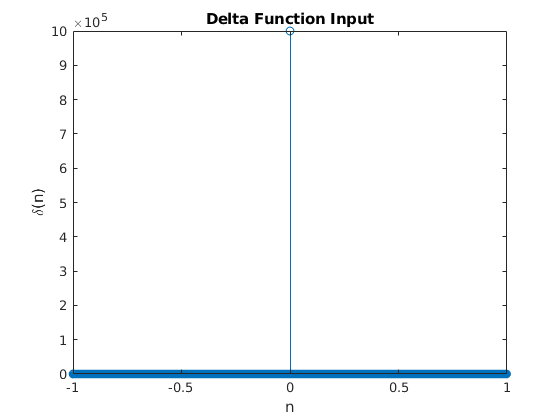

%delta function input
x = -1:1/10000:1;
y = dirac(x);
idx = y == Inf;
y(idx) = 1000000; % set amp of delta function to high value
figure;
stem(x,y)
title('Delta Function Input')
xlabel('n')
ylabel('\delta(n)')

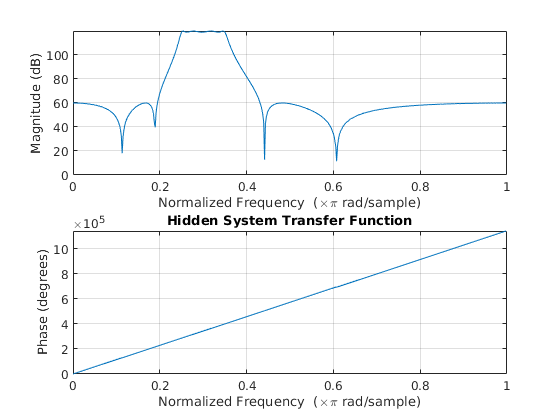

impulse = hidden_system(transpose(y));

%Plot transfer function estimate
figure;
freqz(impulse)
title('Hidden System Transfer Function')




% %delta function input
% x = -1:1/1000000:1;
% y = dirac(x);
% idx = y == Inf; 
% y(idx) = 1000000;     % set amp of delta function to high value
% 
% figure;
% stem(x,y)
% title('Delta Function Input')
% xlabel('n')
% ylabel('\delta(n)')

*The delta function above was inserted into the hidden system.*


% %avg matrix
% avg_vector = hidden_system(transpose(x))

% %Plot transfer function estimate
% figure;
% freqz(avg_vector)
% title('Hidden System Transfer Function')

b) Describe the behavior of the system (what it does to signals).

The system filters input signals using a band pass filter and then applies noise to the output from the filter. 

## Problem 4)

Once again utilize the test signal in the file “test_signal.mat” and estimate the power spectral density, but this time using the Blackman-Tukey method. 

a) Estimate the power spectral density using the Blackman-Tukey method, with an autocorrelation window size of N.

lambda_max = [2048,1024,512,256,128];
Nfft = 2500;
Sx_BT = {};
w = {};

for l = 1:5
    rx_biased=xcorr(test_signal,test_signal,lambda_max(l),'biased');

    %create autocorrelation function of length Nfft with lambda=0 first
    rBT_Nfft = zeros(Nfft,1);
    rBT_Nfft(1:lambda_max(l)+1)=rx_biased(lambda_max(l)+1:2*lambda_max(l)+1);
    rBT_Nfft(Nfft-lambda_max(l)+1:Nfft)=rx_biased(1:lambda_max(l));

    %PSD calculation via fft
    Sx_BT{l}=fft(rBT_Nfft,Nfft);

    w{l}=((0:length(Sx_BT{l})-1)/length(Sx_BT{l})*2*pi);  % frequency range
end

graph = figure;
%set(graph,'Units','normalized','Position',[0 0 1 0.25]); 
subplot(3,2,1)
plot(w{1,1},Sx_BT{1,1})

xlim([0,2*pi])
xlabel('Normalized Frequency')
ylabel('S_{bt}')
title('PSD Est Blackman-Tuckey Method 2^{11}')

subplot(3,2,2)
plot(w{1,2},Sx_BT{1,2})

xlim([0,2*pi])
xlabel('Normalized Frequency')
ylabel('S_{bt}')
title('PSD Est Blackman-Tuckey Method 2^{10}')


subplot(3,2,3)
plot(w{1,3},Sx_BT{1,3})

xlim([0,2*pi])
xlabel('Normalized Frequency')
ylabel('S_{bt}')
title('PSD Est Blackman-Tuckey Method 2^{9}')


subplot(3,2,4)
plot(w{1,4},Sx_BT{1,4})

xlim([0,2*pi])
xlabel('Normalized Frequency')
ylabel('S_{bt}')
title('PSD Est Blackman-Tuckey Method 2^{8}')
subplot(3,2,5)
plot(w{1,5},Sx_BT{1,5})

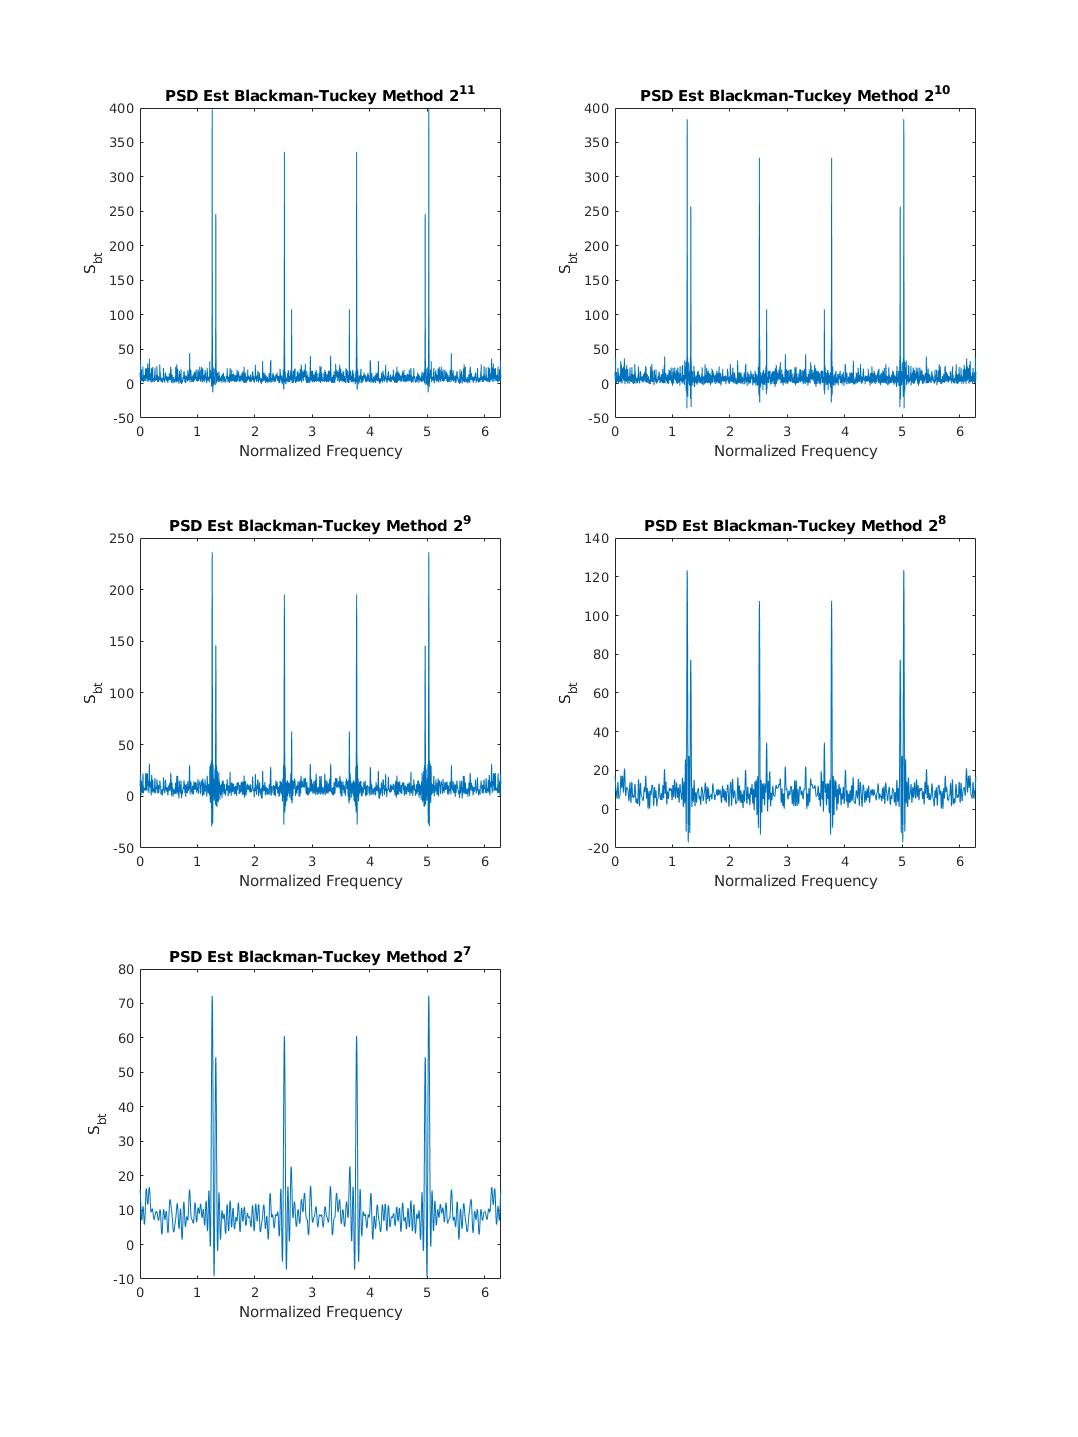

xlim([0,2*pi])
xlabel('Normalized Frequency')
ylabel('S_{bt}')
title('PSD Est Blackman-Tuckey Method 2^{7}') 
set(graph,'Units','normalized','Position',[0 0 1 0.75]); 

*A window size of 2* *$\lambda \max$*+ 1 was adjusted by the lambda max value in powers of 2. A lamba max value of  *$\lambda \max =2^{11}$*was determined to be the best estimate when compared to lower values.*

b) What is the minimum window size N with which you can differentiate the four distinct signal frequencies? 

*The lowest *$\lambda \max$*value at which the four frequencies are visible was determined to be *$\lambda \max =2^8$* based on the above graphs.*

c) What is the window size N that provides the highest SNR?

graph = figure;
% set(graph,'Units','normalized','Position',[0 0 1 0.25]); 
subplot(3,2,1)
plot(w{1,1},10*log10(Sx_BT{1,1}))

xlim([0,2*pi])
xlabel('Normalized Frequency')
ylabel('S_{bt} dB')
title('PSD Est Blackman-Tuckey Method 2^{11}')

subplot(3,2,2)
plot(w{1,2},10*log10(Sx_BT{1,2}))

xlim([0,2*pi])
xlabel('Normalized Frequency')
ylabel('S_{bt} dB')
title('PSD Est Blackman-Tuckey Method 2^{10}')


subplot(3,2,3)
plot(w{1,3},10*log10(Sx_BT{1,3}))

xlim([0,2*pi])
xlabel('Normalized Frequency')
ylabel('S_{bt} dB')
title('PSD Est Blackman-Tuckey Method 2^{9}')


subplot(3,2,4)
plot(w{1,4},10*log10(Sx_BT{1,4}))

xlim([0,2*pi])
xlabel('Normalized Frequency')
ylabel('S_{bt} dB')
title('PSD Est Blackman-Tuckey Method 2^{8}')

subplot(3,2,5)
plot(w{1,5},10*log10(Sx_BT{1,5}))

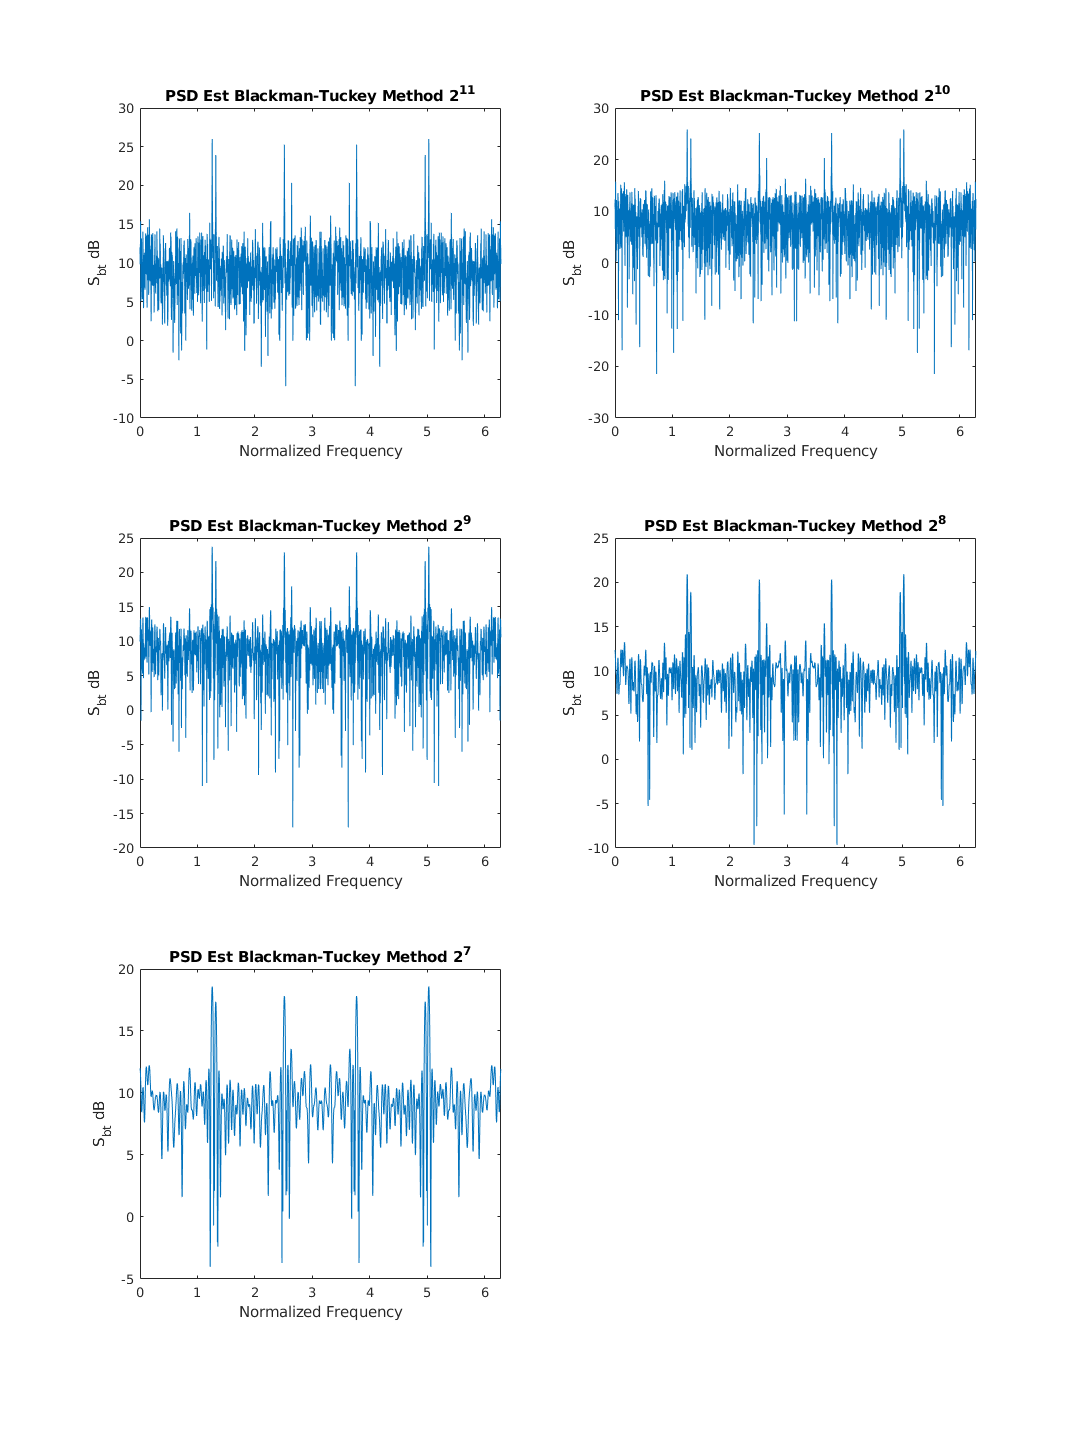

xlim([0,2*pi])
xlabel('Normalized Frequency')
ylabel('S_{bt} dB')
title('PSD Est Blackman-Tuckey Method 2^{7}')
set(graph,'Units','normalized','Position',[0 0 1 0.75]); 

*After inspection of th SNR graphs, an SNR of 4.22 dB was computed for the Blackman-Tuckey PSD estimate of *$\lambda \max$* = *$2^{11}$*. This value is again the largest SNR value and provides the highest frequency resolution of the values tested.*

d) Comment on the advantages and disadvantages of this method with respect to the Bartlett and Welch methods

*This method provides a higher SNR, higher accuracy, and a closer estimate when compared with the Bartlett and Welch methods. The trade off of this method is as variance of the estimation decreases so does the frequency resolution.*

## Problem 5 )

Repeat Problem 3 using the other two methods and compare the results. Comment to the advantages and disadvantages of each method for system identification. Do you manage to get consistent results across all methods?

*Application of a random input signal, using autocorrelation:*

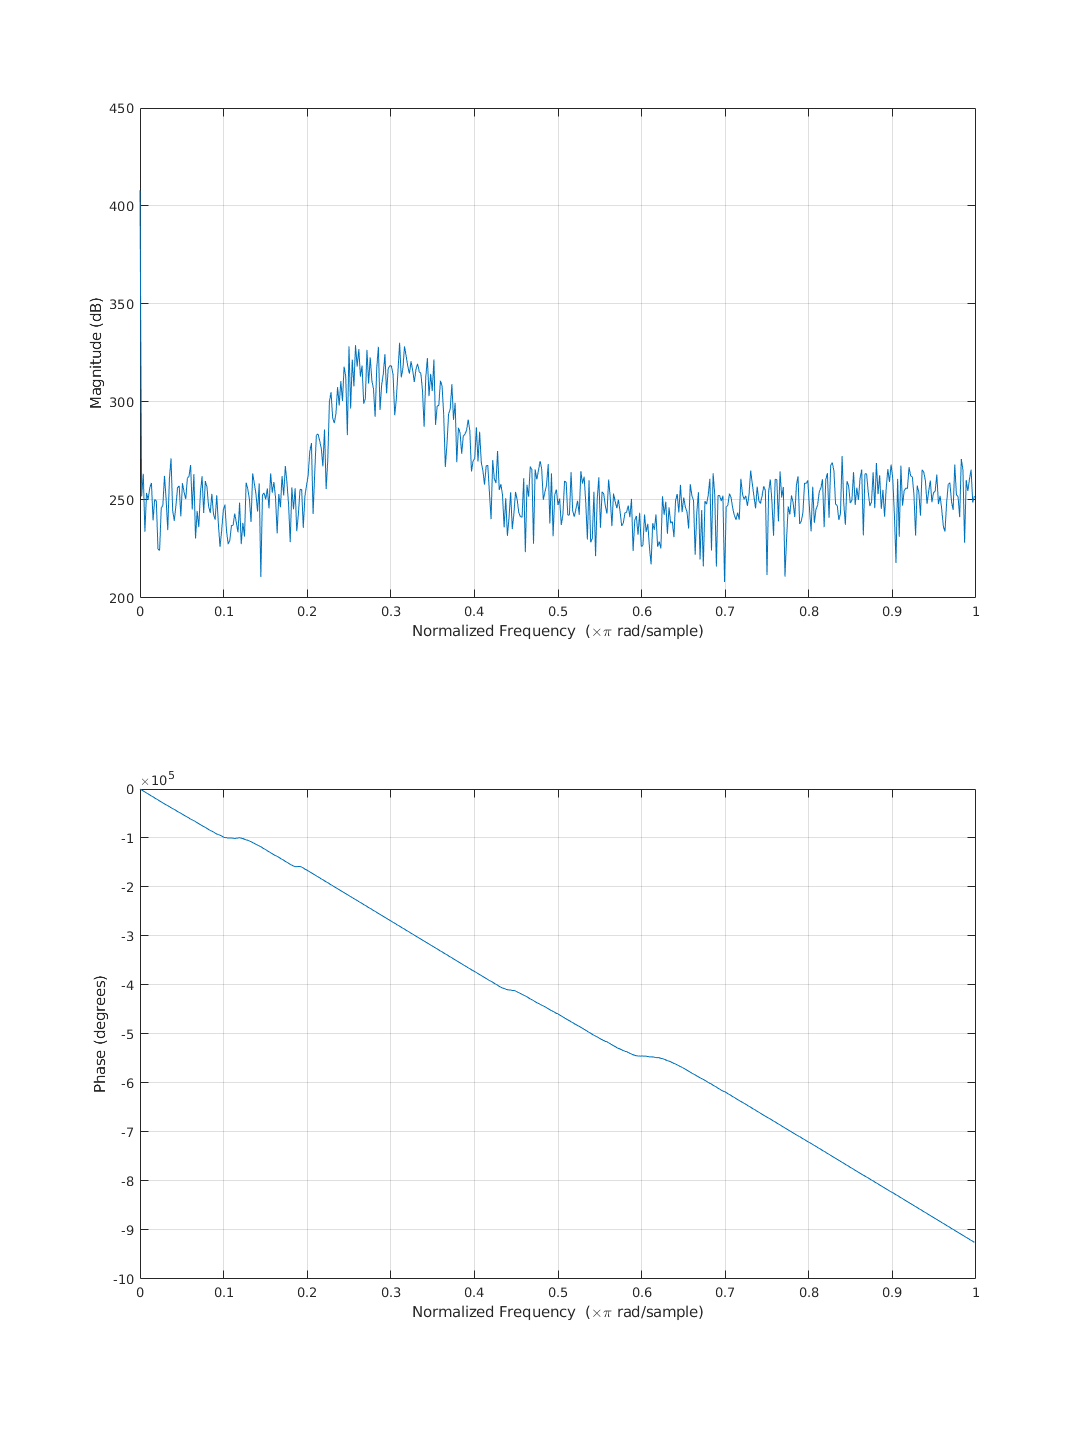

%random vector
r_vect =  (100000).*rand(10000000,1);

y = hidden_system(r_vect);
mean_y = mean(y,1);
y_co = xcorr(r_vect, y);

%transfer function estimate
freqz(y_co);

* The above transfer function estimate was calculated. This estimate is consistent with results of the hidden system's shape from problem 3. However, the function shows noise along the transfer function's shape and a different phase.*

*Feeding a single frequency at a time, and sweeping:*

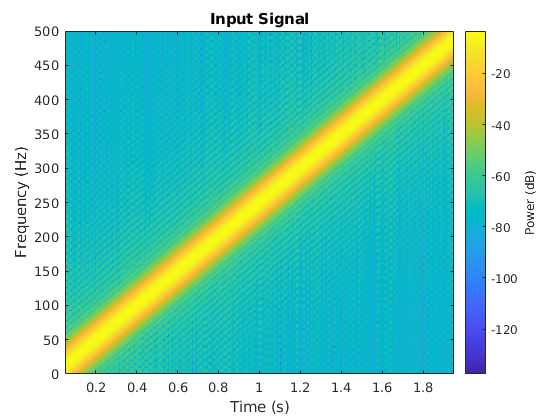

% omega = 0:pi/4:2*pi;
% y_output = zeros(9,1);
% x_input = zeros(9,1);
% for i = 1:length(omega)
%     x_input(i) = cos(i*omega(i));
%     y_output(i) = hidden_system(x_input(i));
% end
figure;
t = 0:1/1e3:2;
x_input = chirp(t,0,1,250);
pspectrum(x_input,1e3,'spectrogram','TimeResolution',0.1, ...
    'OverlapPercent',99,'Leakage',0.85)
title('Input Signal')

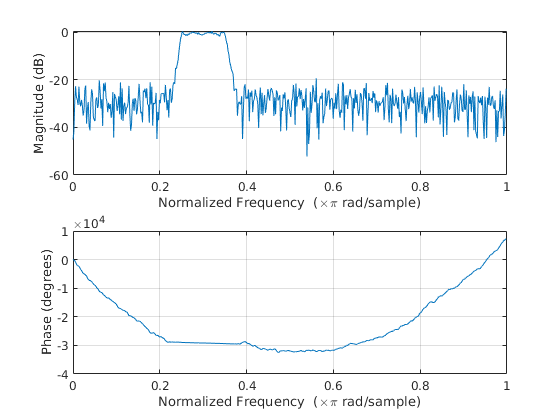

y_output = hidden_system(x_input');
freqz(y_output,x_input');

*The method that provided the best estimate of the hidden system's behavior was inputting a delta function. This method provided a clear result and served as a template for testing the other methods. The autocorrelation method using a random vector showed similar behavior, but showed noise where there should have been a smooth repsonse. The frequency sweeping method was the most challenging method to implement and did not provide consistent results. The other two methods tested provided accurate estimates for the hidden system transfer function behavior.*